clear all;
opts = detectImportOptions('Multipath fading traces (10x50 traces).xlsx')

opts =   SpreadsheetImportOptions with properties:

   Sheet Properties:
                        Sheet: ''

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'Var1', 'Var2', 'Var3' ... and 47 more}
                VariableTypes: {'double', 'double', 'double' ... and 47 more}
        SelectedVariableNames: {'Var1', 'Var2', 'Var3' ... and 47 more}
              VariableOptions: Show all 50 VariableOptions 
	Access Vari

preview('Multipath fading traces (10x50 traces).xlsx',opts)

ans = 8×50 table
     Var1       Var2       Var3        Var4        Var5       Var6       Var7       Var8       Var9       Var10      Var11      Var12      Var13      Var14      Var15     Var16     Var17      Var18      Var19     Var20      Var21      Var22       Var23      Var24      Var25      Var26      Var27      Var28      Var29      Var30      Var31      Var32       Var33      Var34       Var35  

## readmatrix

opts.Sheet = 1;
MFE = readmatrix('Multipath fading traces (10x50 traces).xlsx',opts)

MFE =    -9.5157   -4.7387   -2.0428   -0.8535   -0.9749   -2.6732   -7.4051  -14.3396   -8.6755   -5.3999   -4.1708   -3.3300   -2.2024   -0.6098    1.1544    1.8025    1.3706    0.8723    1.1001    1.5796    1.1923   -0.1944   -3.1353  -11.0556  -13.0499   -5.0626   -3.1258   -4.1969   -5.7984   -4.9619   -2.4995   -0.3324    0.3016   -0.7020   -3.3483   -5.2958   -4.8528   -4.9516   -4.8039   -3.9389   -2.1336   -0.2122    1.1216    1.0668   -1.1108   -5.3233   -8.1483   -5.2516   -2.9805   -2.4235
   -9.2266   -4.5930   -1.9532   -0.7876   -0.9234   -2.6378   -7.3771  -14.1796   -8.5878   -5.3314   -4.0956   -3.2580   -2.1475   -0.5656    1.1837    1.8136    1.3650    0.8566    1.0797    1.5521    1.1613   -0.2221   -3.1688  -11.1167  -12.8530   -5.0220   -3.1242   -4.2143   -5.8130   -4.9624   -2.4849   -0.3174    0.3053   -0.7193   -3.3908   -5.3398   -4.8850   -4.9553   -4.7589   -3.8820   -2.0976   -0.1923    1.1269    1.0521   -1.1526   -5.4128   -8.2658   -5.2983   -2.9988   

## calculation


ISD = 1;
R = ISD/2;

Signal_transmitted = 1000*20/50;

for j=1:50 %PRB loop 50
A=MFE(:,j);

 %user0

S_received = pow2db(Signal_transmitted)+pathgain(R/10)+A;

interference_mpf=zeros(5000,36);

for b=1:36 %cell loop
B=circshift(A,5000-135*b);
interference_mpf(:,b)=B;
end
%calculation for interference

for i = 1:36
    if i <=6
        interference_tier(:,i) = pow2db(Signal_transmitted)+pathgain(ISD)+interference_mpf(:,i);
    elseif i<=18 && i>6
        interference_tier(:,i) = pow2db(Signal_transmitted)+pathgain(2*ISD)+interference_mpf(:,i);     
    elseif i>=19
        interference_tier(:,i) = pow2db(Signal_transmitted)+pathgain(3*ISD)+interference_mpf(:,i);
    end
end

interference_tier = db2pow(interference_tier);
interference = sum(interference_tier,2);
N = 1.3806488*10^(-23)*290*180000*1000 %mW;


SINR=db2pow(S_received)./ ((interference)+N);
SINRw(:,j) = SINR;
SINRdb(:,j) = pow2db(SINR);

end

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

N = 7.2070e-13

## plot chart

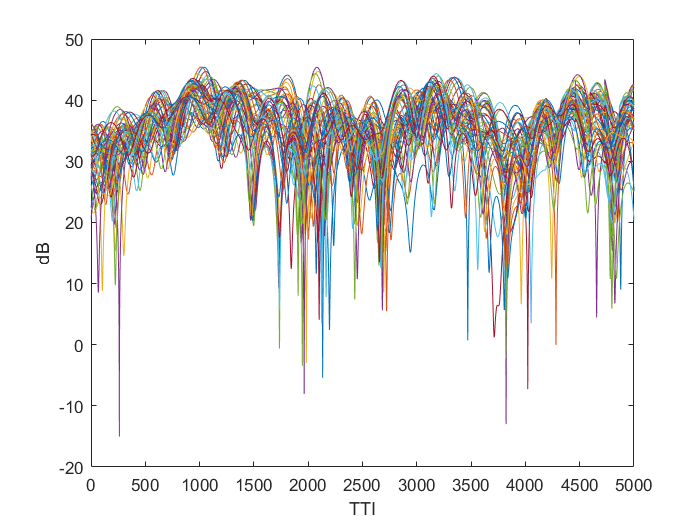


figure
  plot(SINRdb);
    ylabel('dB')
    xlabel('TTI')
set(gca,'FontSize',10);

## shannon chart

figure(2)
B = 0.18 %MHz

B = 0.1800

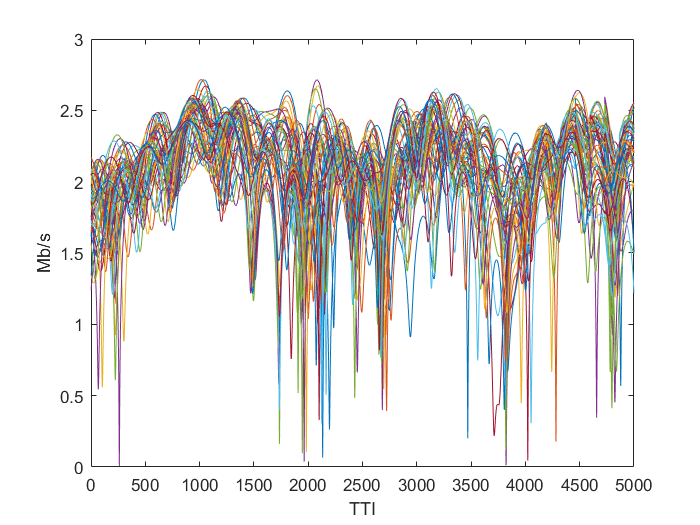

x = 1:5000;
for i = 1:50
    %% shannon formula
    Bit_rate(:,i) = real(B*log2(1+SINRw(:,i)));
end
Y = Bit_rate';
figure(2)
    plot(Bit_rate);
    ylabel('Mb/s')
    xlabel('TTI')


Aggregate_Y = sum(Y)    

Aggregate_Y =    92.5406   92.5778   92.6125   92.6446   92.6742   92.7014   92.7264   92.7490   92.7695   92.7878   92.8040   92.8182   92.8304   92.8407   92.8491   92.8557   92.8605   92.8636   92.8650   92.8648   92.8630   92.8597   92.8549   92.8487   92.8411   92.8322   92.8221   92.8106   92.7981   92.7844   92.7696   92.7537   92.7369   92.7191   92.7004   92.6807   92.6602   92.6387   92.6163   92.5930   92.5688   92.5435   92.5173   92.4899   92.4613   92.4314   92.4002   92.3675   92.3332   92.2971


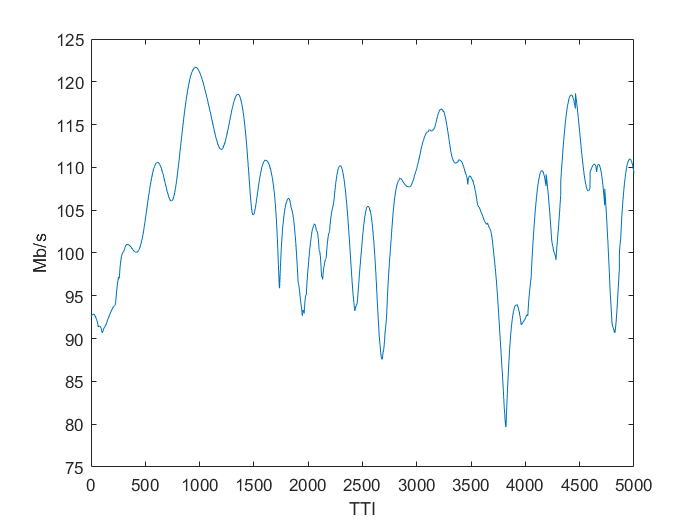

plot(Aggregate_Y)
ylabel('Mb/s')
xlabel('TTI')

mean(Aggregate_Y)

ans = 105.4399